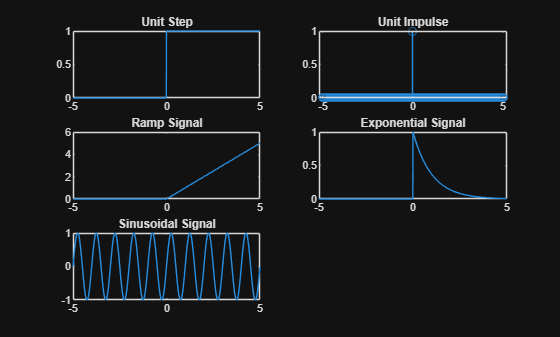

clc;
clear;
close all;

%% -------------------------------
% 1. Time Vector
%% -------------------------------
t = -5:0.01:5;

%% -------------------------------
% 2. Basic Signals
%% -------------------------------
% Unit Step
u = double(t >= 0);

% Unit Impulse (approximation)
delta = zeros(size(t));
delta(t == 0) = 1;

% Ramp Signal
r = t .* (t >= 0);

% Exponential Signal
a = 1;
exp_sig = exp(-a*t) .* (t >= 0);

% Sinusoidal Signal
f = 1; % frequency
sin_sig = sin(2*pi*f*t);

%% -------------------------------
% 3. Plot Basic Signals
%% -------------------------------
figure;
subplot(3,2,1); plot(t,u); title('Unit Step');
subplot(3,2,2); stem(t,delta); title('Unit Impulse');
subplot(3,2,3); plot(t,r); title('Ramp Signal');
subplot(3,2,4); plot(t,exp_sig); title('Exponential Signal');
subplot(3,2,5); plot(t,sin_sig); title('Sinusoidal Signal');

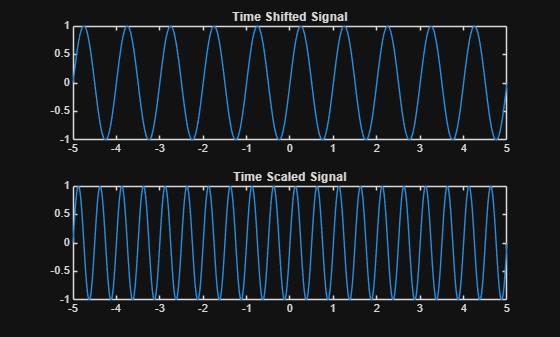


%% -------------------------------
% 4. Time Domain Operations
%% -------------------------------
% Time Shifting
shift = 2;
x_shift = sin(2*pi*f*(t - shift));

% Time Scaling
scale = 2;
x_scale = sin(2*pi*f*(scale*t));

figure;
subplot(2,1,1); plot(t,x_shift); title('Time Shifted Signal');
subplot(2,1,2); plot(t,x_scale); title('Time Scaled Signal');

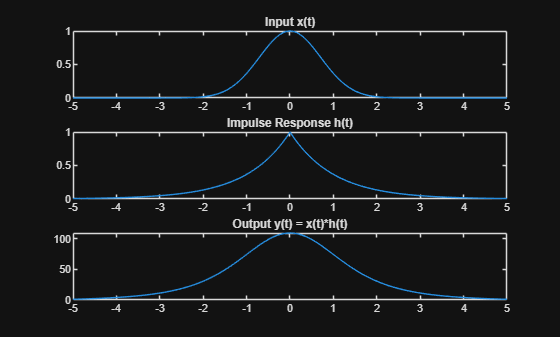


%% -------------------------------
% 5. Convolution (LTI System)
%% -------------------------------
x = exp(-t.^2);   % input signal
h = exp(-abs(t)); % impulse response

y = conv(x, h, 'same'); % convolution

figure;
subplot(3,1,1); plot(t,x); title('Input x(t)');
subplot(3,1,2); plot(t,h); title('Impulse Response h(t)');
subplot(3,1,3); plot(t,y); title('Output y(t) = x(t)*h(t)');

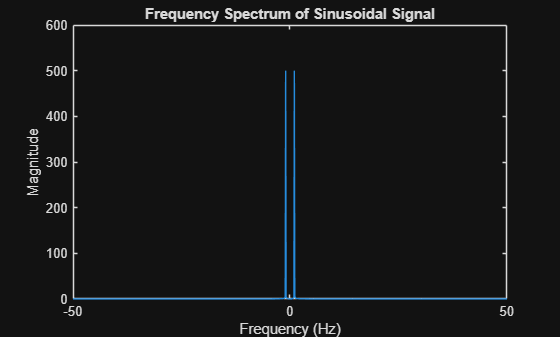


%% -------------------------------
% 6. Frequency Domain Analysis
%% -------------------------------
Fs = 100; % sampling frequency
N = length(t);

X = fftshift(fft(sin_sig));
freq = linspace(-Fs/2, Fs/2, N);

figure;
plot(freq, abs(X));
title('Frequency Spectrum of Sinusoidal Signal');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

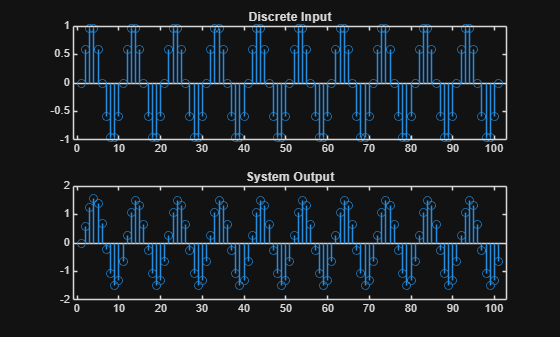


%% -------------------------------
% 7. System Simulation using filter
%% -------------------------------
% Define system: y[n] - 0.5y[n-1] = x[n]
b = [1];        % numerator
a = [1 -0.5];   % denominator

x_discrete = sin(2*pi*0.1*(0:100)); % input
y_discrete = filter(b, a, x_discrete);

figure;
subplot(2,1,1); stem(x_discrete); title('Discrete Input');
subplot(2,1,2); stem(y_discrete); title('System Output');


%% -------------------------------
% 8. Laplace Transform (Symbolic)
%% -------------------------------
syms t s
x_t = exp(-2*t);
X_s = laplace(x_t);

disp('Laplace Transform of exp(-2t):');

Laplace Transform of exp(-2t):


disp(X_s);

$$\frac{1}{s+2}$$


%% -------------------------------
% 9. Fourier Transform (Symbolic)
%% -------------------------------
syms w
x_t = exp(-t^2);
X_w = fourier(x_t);

disp('Fourier Transform of exp(-t^2):');

Fourier Transform of exp(-t^2):


disp(X_w);

$$\sqrt{\pi }\,{\mathrm{e}}^{-\frac{w^{2}}{4}}$$